Parameters

m_c=1.5 

m_c = 1.5000

m_p=0.5

m_p = 0.5000

g=9.82

g = 9.8200

L=1

L = 1

d_1=0.01

d_1 = 0.0100

d_2=0.01

d_2 = 0.0100

1.1

A=[0,0,1,0;0,0,0,1;0,g*m_p/m_c,-d_1/m_c,-d_2/(L*m_c);0,g*(m_p+m_c)/(L*m_c),-d_1/(L*m_c),-d_2*(m_c+m_p)/(L*L*m_c*m_p)]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067   -0.0267



B=[0;0;1/m_c;1/(L*m_c)]

B =          0
         0
    0.6667
    0.6667



C = [0 1 0 0]

C =      0     1     0     0



D=0

D = 0


sys = ss(A,B,C,D)

sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



1.2

p = pole(sys)

p =    -3.6327
    3.6043
   -0.0050
         0


e=eig(sys)

e =    -3.6327
    3.6043
   -0.0050
         0


[z,g]=zero(sys)

z = 	1.0e+-16 *

    0.2933
         0


g = 0.6667

s = isstable(sys)

s = logical
   0


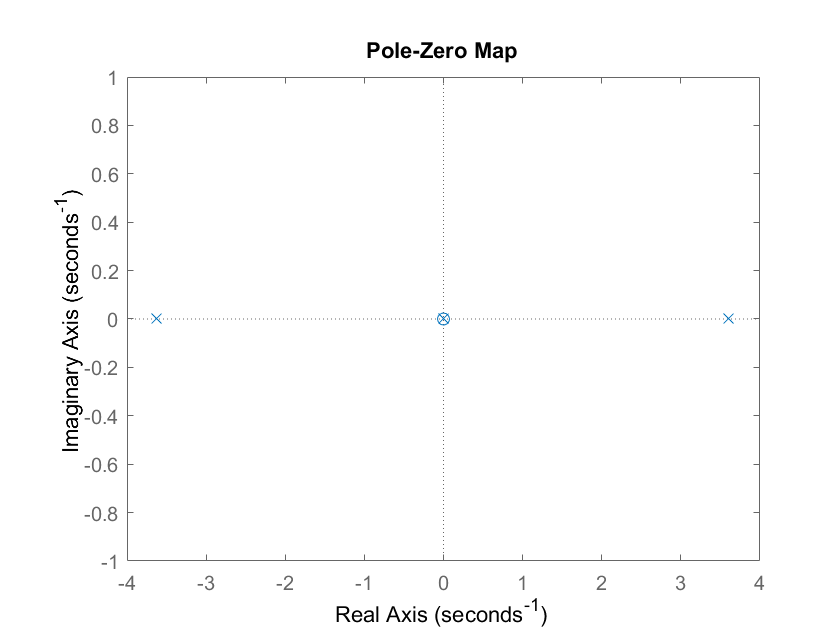

pzmap(sys)

1.3

tfunc = tf(sys)

tfunc =
 
          0.6667 s - 1.956e-17
  -------------------------------------
  s^3 + 0.03333 s^2 - 13.09 s - 0.06547
 
Continuous-time transfer function.



[num,den] = ss2tf(A,B,C,D);
sys = tf(num,den)

sys =
 
    0.6667 s^2 + 2.333e-17 s + 3.186e-16
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.



[z,p,k] = ss2zp(A,B,C,D);
sysm = zpk(z,p,k)

sysm =
 
     0.66667 (s^2 + 4.779e-16)
  -------------------------------
  s (s+3.633) (s-3.604) (s+0.005)
 
Continuous-time zero/pole/gain model.

